#  Load, register, segment and neuropil correct 2P data

## Path names

fn_base = '\\duhs-user-nc1.dhe.duke.edu\dusom_glickfeldlab\All_Staff';
lg_fn = fullfile(fn_base, 'home\lindsey');
data_fn = fullfile(lg_fn, 'Tutorials\2p_data');
mworks_fn = fullfile(lg_fn, 'Tutorials\Behavior_data');
fnout = fullfile(lg_fn, 'Tutorials\Analysis');

## Specific experiment information

date = '260112';
ImgFolder = '002';
time = '1425';
mouse = 'i1428';
frame_rate = 15;
run_str = catRunName(ImgFolder, 1);
datemouse = [date '_' mouse];
datemouserun = [date '_' mouse '_' run_str];

## Load 2P data

Load mworks data (stimulus and behavior information)

fName = fullfile(mworks_fn, ['data-' mouse '-' date '-' time '.mat']);
load(fName);

Load 2P metadata

CD = fullfile(data_fn, mouse, date, ImgFolder);
cd(CD);
imgMatFile = [ImgFolder '_000_000.mat'];
load(imgMatFile);

Load 2P images

totframes = input.counterValues{end}(end); %this is from the mworks structure- finds the last value clocked for frame count
fprintf(['Reading ' num2str(totframes) ' frames \r\n'])

Reading 14400 frames 


data = sbxread([ImgFolder '_000_000'],0,totframes);

Data is nPMT x nYpix x nXpix x nframes. 

fprintf(['Data is ' num2str(size(data))])

Data is 1    529    796  14400

When imaging a single channel, nPMT = 1, so squeeze:

data = squeeze(data);

## Register 2P data

Goal here is to remove X-Y movement artifacts

1. Find a stable target

    a. Plot average of 500 frames throughout stack

nframes = 500; %nframes to average
nskip = 1500; %nframes to skip for each average

nep = floor(size(data,3)./nskip);
[n n2] = subplotn(nep); 
figure('units','normalized','outerposition',[0 0 1 1]);
for i = 1:nep; 
    subplot(n,n2,i); 
    imagesc(mean(data(:,:,1+((i-1)*nskip):nframes+((i-1)*nskip)),3)); 
    title([num2str(1+((i-1)*nskip)) '-' num2str(nframes+((i-1)*nskip))]); 
end


    b. GUI to select target image- choose one that is sharp and close to center of stack

f=gcf;
w = waitforbuttonpress; %click on subplot
if w == 0
    axesClicked = gca;
    allAxes = flipud(findobj(f.Children,'Type','axes'));
    numClicked = find(axesClicked==allAxes);
    close all
end
fprintf(['Selected subplot ' num2str(numClicked)])

Selected subplot 6

    c. Create target image

data_avg = mean(data(:,:,1+((numClicked-1)*nskip):nframes+((numClicked-1)*nskip)),3); 

2. stackRegister minimizes the difference of each frame from the target

[out, data_reg] = stackRegister(data,data_avg);

Starting, frame 0
Frame 250 (12.9 fps)
Frame 500 (14.1 fps)
Frame 750 (14.7 fps)
Frame 1000 (15.0 fps)
Frame 1250 (15.1 fps)
Frame 1500 (15.2 fps)
Frame 1750 (15.2 fps)
Frame 2000 (15.3 fps)
Frame 2250 (15.4 fps)
Frame 2500 (15.4 fps)
Frame 2750 (15.5 fps)
Frame 3000 (15.5 fps)
Frame 3250 (15.5 fps)
Frame 3500 (15.5 fps)
Frame 3750 (15.5 fps)
Frame 4000 (15.5 fps)
Frame 4250 (15.6 fps)
Frame 4500 (15.6 fps)
Frame 4750 (15.6 fps)
Frame 5000 (15.6 fps)
Frame 5250 (15.6 fps)
Frame 5500 (15.7 fps)
Frame 5750 (15.7 fps)
Frame 6000 (15.7 fps)
Frame 6250 (15.7 fps)
Frame 6500 (15.7 fps)
Frame 6750 (15.8 fps)
Frame 7000 (15.8 fps)
Frame 7250 (15.8 fps)
Frame 7500 (15.8 fps)
Frame 7750 (15.8 fps)
Frame 8000 (15.8 fps)
Frame 8250 (15.8 fps)
Frame 8500 (15.8 fps)
Frame 8750 (15.8 fps)
Frame 9000 (15.8 fps)
Frame 9250 (15.8 fps)
Frame 9500 (15.8 fps)
Frame 9750 (15.8 fps)
Frame 10000 (15.8 fps)
Frame 10250 (15.8 fps)
Frame 10500 (15.8 fps)
Frame 10750 (15.8 fps)
Frame 11000 (15.8 fps)
Frame 11250 

New average image after registration

data_reg_avg = mean(data_reg,3);

Save registration shifts and target, and mworks data

mkdir(fullfile(fnout, datemouse, datemouserun))
save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_reg_shifts.mat']), 'data_reg_avg', 'out', 'data_avg')
save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_input.mat']), 'input')

Test registration

     a. Make sure first and last images are sharp and similar. Focus on vasculature and nuclei- not cells since F changes

figure;
ind = [1 nep];
for i = 1:length(ind) 
    subplot(2,1,i); 
    ix = ind(i);
    imagesc(mean(data_reg(:,:,1+((ix-1)*nskip):nframes+((ix-1)*nskip)),3)); 
    title([num2str(1+((ix-1)*nskip)) '-' num2str(nframes+((ix-1)*nskip))]); 
end
print(fullfile(fnout, datemouse, datemouserun, [datemouserun '_FOV_first&last.pdf']), '-dpdf')

    b. Average of all frames should be sharp

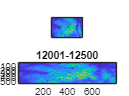

figure;
imagesq(data_reg_avg); 
print(fullfile(fnout, datemouse, datemouserun, [datemouserun '_FOV_avg.pdf']), '-dpdf')

clear data

## Segment 2P data

Goal here is to create a cell mask to extract fluorescence timecourses

1. Find activated cells

    a. Reshape data stack to segregate trials 

    First need to know how many frames per trial and how many trials to create trial matrix

nOn = input.nScansOn;
nOff = input.nScansOff;
ntrials = size(input.tGratingDirectionDeg,2); %this is a cell array with one value per trial, so length = ntrials
sz = size(data_reg);

%empty matrix with dimensions of field of view (sz(1) sz(2)), trial duration (nOn plus half of the preceding off period nOff/2), number of trials (ntrials)
data_tr = zeros(sz(1),sz(2),(nOff/2)+nOn, ntrials);
fprintf(['Size of data_tr is ' num2str(size(data_tr)) '\n'])

    Then need to know when each trial starts using the photodiode signal

[stimOn stimOff] = photoFrameFinder_Sanworks(info.frame); %info.frame is from scanbox

    And use those frames to sort the experiment into trials

for it = 1:ntrials
    data_tr(:,:,:,it) = data_reg(:,:,stimOn(it)-(nOff/2):stimOn(it)+nOn-1);
end

 b. Find baseline F from last half of off period- avoids decay of previous on trial

data_f = mean(data_tr(:,:,1:nOff/2,:),3); 

    c. Find dF/F for each trial

data_df = bsxfun(@minus, double(data_tr), data_f); 
data_dfof = bsxfun(@rdivide,data_df, data_f); 
clear data_f data_df data_tr

    d. Find average dF/F for each stimulus condition (this is for an experiment with changing grating direction)

Dir = celleqel2mat_padded(input.tGratingDirectionDeg); %transforms cell array into matrix (1 x ntrials)
Dirs = unique(Dir);
nDirs = length(Dirs);
data_dfof_avg = zeros(sz(1),sz(2),nDirs); %create empty matrix with FOV for each direction: nYpix x nXPix x nDir

nStim = nDirs;
[n n2] = subplotn(nDirs); %function to optimize subplot number/dimensions
for idir = 1:nDirs
    ind = find(Dir == Dirs(idir)); %find all trials with each direction
    data_dfof_avg(:,:,idir) = mean(mean(data_dfof(:,:,nOff/2+1:end,ind),3),4); %average all On frames and all trials
    subplot(n,n2,idir)
    imagesc(data_dfof_avg(:,:,idir))
end
clear data_dfof

        Filtering data helps make cells more visible for selection

myfilter = fspecial('gaussian',[20 20], 0.5);
data_dfof_avg_all = imfilter(data_dfof_avg,myfilter);
data_dfof_max = max(data_dfof_avg_all,[],3); %finds all active cells by taking max projection

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_stimActFOV.mat']), 'data_dfof_max', 'data_dfof_avg_all', 'nStim')

    2. Create cell masks from active cells

        Concatenate images of max and all directions

data_dfof = cat(3,data_dfof_max, data_dfof_avg_all);

        Set up empty matrices for segmenting cells

mask_data = data_dfof;
mask_exp = zeros(sz(1),sz(2));
mask_all = zeros(sz(1), sz(2));

        a. Click on bright cells in mask to create mask- blue shading should fill bright region of single cell evenly.  

            If cell not filled well, press 'z' or shift+click to remove. Try again by 1) clicking on different spot- brighter spot will make fill smaller- if there are two cells also helps to fill brighter cell first; 2) change threshold- higher thresh will make fill smaller; 3) wait for different image where cell might be more distinct from background

            Press 'return' when done with each image. 

            Next images will have black spots where cells were previously selected- don't let new masks encroach on old cells or will fuse. imCellBuffer helps with this.

for iStim = 1:size(data_dfof,3)    
    mask_data_temp = mask_data(:,:,iStim);
    mask_data_temp(find(mask_exp >= 1)) = 0; %blacks out old cells
    bwout = imCellEditInteractiveLG(mask_data_temp); %selection GUI
    mask_all = mask_all+bwout; %adds new cells to old cells
    mask_exp = imCellBuffer(mask_all,3)+mask_all; %creates buffer around cells to avoid fusing
    close all
end

        b. Number independent regions for mask

mask_cell = bwlabel(mask_all); %turns logical into numbered cells
figure;
imagesc(mask_cell)

        c. Create neuropil masks (these are regions around each cell without overlap from neighboring cells)

nMaskPix = 5; %thickness of neuropil ring in pixels
nBuffPix = 3; %thickness of buffer between cell and ring
mask_np = imCellNeuropil(mask_cell,nBuffPix,nMaskPix);

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_mask_cell.mat']), 'data_dfof_max', 'mask_cell', 'mask_np')
clear data_dfof data_dfof_avg max_dfof mask_data mask_all mask_2 data_base data_base_dfof data_targ data_targ_dfof data_f data_base2 data_base2_dfof data_dfof_dir_all data_dfof_max data_dfof_targ data_avg data_dfof2_dir data_dfof_dir 

## Neuropil subtraction

Goal is to remove contamination from out-of-focus fluorescence

- Extract cell timecourses

data_tc = stackGetTimeCourses(data_reg, mask_cell); %applies mask to stack to get timecourses

            Timecourses are nFrames x nCells

fprintf(['data_tc is ' num2str(size(data_tc))]) 

data_tc is 14400    117

nCells = size(data_tc,2);

            Downsampled timecourses for neuropil subtraction- averageing decreases noise

down = 5; %number of frames to average
data_reg_down = stackGroupProject(data_reg,down); %averages every 5 frames in stack  
data_tc_down = stackGetTimeCourses(data_reg_down, mask_cell);    

        2.  Extract neuropil timecourses (full and downsampled)

sz = size(data_reg);
np_tc = zeros(sz(3),nCells);
np_tc_down = zeros(floor(sz(3)./down), nCells);
for i = 1:nCells
     np_tc(:,i) = stackGetTimeCourses(data_reg,mask_np(:,:,i));
     np_tc_down(:,i) = stackGetTimeCourses(data_reg_down,mask_np(:,:,i));
     fprintf(['Cell #' num2str(i) '%s\n']) 
end

Cell #1Cell #2Cell #3Cell #4Cell #5Cell #6Cell #7Cell #8Cell #9Cell #10Cell #11Cell #12Cell #13Cell #14Cell #15Cell #16Cell #17Cell #18Cell #19Cell #20Cell #21Cell #22Cell #23Cell #24Cell #25Cell #26Cell #27Cell #28Cell #29Cell #30Cell #31Cell #32Cell #33Cell #34Cell #35Cell #36Cell #37Cell #38Cell #39Cell #40Cell #41Cell #42Cell #43Cell #44Cell #45Cell #46Cell #47Cell #48Cell #49Cell #50Cell #51Cell #52Cell #53Cell #54Cell #55Cell #56Cell #57Cell #58Cell #59Cell #60Cell #61Cell #62Cell #63Cell #64Cell #65Cell #66Cell #67Cell #68Cell #69Cell #70Cell #71Cell #72Cell #73Cell #74Cell #75Cell #76Cell #77Cell #78Cell #79Cell #80Cell #81Cell #82Cell #83Cell #84Cell #85Cell #86Cell #87Cell #88Cell #89Cell #90Cell #91Cell #92Cell #93Cell #94Cell #95Cell #96Cell #97Cell #98Cell #99Cell #100Cell #101Cell #102Cell #103Cell #104Cell #105Cell #106Cell #107Cell #108Cell #109Cell #110Cell #111Cell #112Cell #113Cell #114Cell #115Cell #116Cell #117

        3. Find best neuropil weights by maximizing skew on downsampled subtractions

            Assumes calcium signals are 1) sparse and 2) positive.  Too little subtraction will decrease sparseness and too much will make signals negative. Thus, the best neuropil subtraction should yield the highest skew.

        a. Measure skew for all weights:

ii= 0.01:0.01:1;
x = zeros(length(ii), nCells);
for i = 1:100
    x(i,:) = skewness(data_tc_down-tcRemoveDC(np_tc_down*ii(i)));
end

        b. Find index with highest skew for each cell

[max_skew ind] =  max(x,[],1); 

        c. convert to weight

np_w = 0.01*ind; 

        4. Subtract weighted neuropil response from full timecourses

npSub_tc = data_tc-bsxfun(@times,tcRemoveDC(np_tc),np_w);
clear data_reg data_reg_down

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_TCs.mat']), 'data_tc', 'np_tc', 'npSub_tc')

## Behavior data extraction: Running and Pupil

Goal is to extract running speed and pupil size/position and align to trial structure

- Extract wheel data- function gives average running speed for each imaging frame

wheel_tc = wheelSpeedCalc(input,32,'purple'); %input, ticks, wheelID
wheel_tr = zeros(1,ntrials); 
for it = 1:ntrials
    wheel_tr(it) = mean(wheel_tc(1,stimOn(it):stimOn(it)+nOn-1),2);
end
figure; 
plot(wheel_tr)
ylabel('Speed (cm/s)')
xlabel('Trial')

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_wheelSpeed.mat']), 'wheel_tc', 'wheel_tr')

           2. Extract pupil data

                a. Load pupil data

fn = [ImgFolder '_000_000_eye.mat'];
data_temp = load(fn);
data = squeeze(data_temp.data);
clear data_temp

               b. Crop pupil data- first plot mean image and then select a rectangle for finding the pupil. Need to isolate region of eye that has eye but limited light artifacts

data_avg = mean(data,3);
imagesc(data_avg); movegui('center') % plot mean image

ax = gca;
rect = round(getrect(ax));
datat = data_avg(rect(2):rect(2)+rect(4),rect(1):rect(1)+rect(3));
figure; imagesc(datat)

data_crop = data(rect(2):rect(2)+rect(4),rect(1):rect(1)+rect(3),:);

               b. Segment pupil data. First set the range of pupil sizes (radius in pixels), then extract using extractEyeData. 

                Plots will show example images where eye was well segmented as well as when it wasn't. If noisy or missing frames then adjust radius in search.

                Plot also shows histogram of found sizes- ideally, does not peak at smallest size (suggests that it is missing some smaller pupils).

rad_range = [3 25]; %adjust to expected range of pupil size (if low end is too small then may find noisy bright stuff)
Eye_data = extractEyeData(data_crop,rad_range);

               c. Extract radius and centroid info from Eye_data structure, and make frames pupil was not found NaN.

Rad_temp = sqrt(Eye_data.Area./pi);
Centroid_temp = Eye_data.Centroid;
Rad_temp(Eye_data.badFrames,:) =nan(length(Eye_data.badFrames),1);
Centroid_temp(Eye_data.badFrames,:) = nan(length(Eye_data.badFrames),2);

               d. Align to trial structure- fill in NaNs through extrapolation if enough data.

rad.tc = zeros((nOff/2)+nOn, ntrials);
centroid.tc = zeros((nOff/2)+nOn,2, ntrials);
calib = 1/26.6; %mm per pixel
for it = 1:ntrials
    crange = stimOn(it)-(nOff/2):stimOn(it)+nOn-1;
    rad.tc(:,it) = Rad_temp(crange,:).*calib;
    centroid.tc(:,:,it) = Centroid_temp(crange,:).*calib;
end
rad.stim = nanmean(rad.tc(1+nOff/2:end,:),1); %average over stim window
centroid.stim = squeeze(nanmean(centroid.tc(1+nOff/2:end,:,:),1))./0.025;

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_eye.mat']), 'centroid', 'rad', 'rect', 'rad_range')

%plot eye position across trials 
figure; subplot(2,1,1)
scatter(centroid.stim(1,:),centroid.stim(2,:), [], rad.stim); colorbar
ind = find(~isnan(centroid.stim(1,:)));
centroid.med = findMaxNeighbors(centroid.stim(:,ind),2); %function to f
hold on;
scatter(centroid.med(1),centroid.med(2),'or')
centroid.dist = sqrt((centroid.stim(1,:)-centroid.med(1)).^2 + (centroid.stim(2,:)-centroid.med(2)).^2);
title('Color- radius')
xlabel('x-pos')
ylabel('y-pos')
subplot(2,1,2)
hist(centroid.dist,0:0.5:60)
title([num2str(sum(centroid.dist<4)) ' trials w/in 4 deg'])
sgtitle([num2str(sum(~isnan(centroid.dist))) '/' num2str(nTrials) ' measurable trials'])
xlabel('Centroid distance from median')